# Circular domain: forward simulation

First OSMI example: compute and visualise the electromagnetic field radiated by each antenna of a circular array into a circular Domain of Interest (DOI). The DOI is filled with a homogeneous medium.

The scenario has

- a square computational domain terminated in a PML (Perfectly Matched Layer),

- a circular DOI filled with a matching medium,

- a circular array of line-sources around the DOI.

`generate``_f``ields` meshes the scenario, solves the field of every transmitter with the FEM solver and saves it in `results/` under the scenario name.

Units are SI (m, Hz, S/m) and the time convention is $e^{+j\omega t}$.

## Setup

clc; close all; clear;
here = fileparts(mfilename('fullpath'));                       % folder of this example
if ~isfolder(fullfile(here, '..', '..', 'Forward_solvers'))      % Live Editor: use the open file
    try, here = fileparts(matlab.desktop.editor.getActiveFilename); catch, here = pwd; end
end
addpath(fullfile(here, '..', '..'));
setup_osmi;
resultsDir = fullfile(here, 'results');

## Frequency

sim.f = 1e9;                                   % Hz

## Materials

Each region is described by its relative permittivity $\varepsilon'$ and conductivity $\sigma$. The solver uses the complex relative permittivity


$$\varepsilon_c = \varepsilon' - j\,\frac{\sigma}{\omega\,\varepsilon_0}$$


- `background`: medium outside the DOI

- `doi`: matching medium filling the DOI

materials.background.epsr  = 20;
materials.background.sigma = 0.02;             % S/m

materials.doi.epsr  = 20;
materials.doi.sigma = 0.02;

## Geometry

DOI of radius `doiRadius` and `nAntennas` line sources on a circle of radius `antennaRing`. The outer square and the PML are sized automatically from the geometry.

geom.doiRadius   = 0.10;
geom.antennaRing = 0.12;
geom.nAntennas   = 12;

## Mesh control

The element size $h$ follows the wavelength in each medium,


$$\lambda = \frac{c_0}{f\sqrt{\varepsilon'}}$$


with the rule of thumb $h=\lambda/10$ (minimum), $\lambda/12$ (good), $\lambda/15$ (high accuracy). The antennas are small discs of radius `rAnt` so that the mesh has a node at each antenna.

c0         = 299792458;
lambda_doi = c0/(sim.f*sqrt(materials.doi.epsr));
lambda_bg  = c0/(sim.f*sqrt(materials.background.epsr));

meshControl.hDOI = lambda_doi/12;
meshControl.hBG  = lambda_bg/12;
meshControl.hAnt = lambda_bg/15;
meshControl.rAnt = meshControl.hAnt;

## Generate the fields

One FEM solve per transmitting antenna; the result is saved as `results/domain.mat`.

opts.name      = "domain";
opts.outputDir = resultsDir;
opts.current   = 1e-3;                         % A
[domain, scenario] = generate_fields(sim, materials, geom, meshControl, opts);

[domain] geometry radius 0.124 m -> square 0.498 m, PML from 0.187 m (0.062 m thick, gap 0.062 m)
[domain] mesh: 9217 nodes, 18076 triangles; solving 12 sources ...
Saved "domain"  ->  C:\Users\ibeb\OneDrive - Ciências ULisboa\Doutoramento\Coisas uteis\School_Turim\Matlab\Examples\Circular_domain\results\domain.mat


## Geometry and mesh

The dashed red square marks the start of the PML.

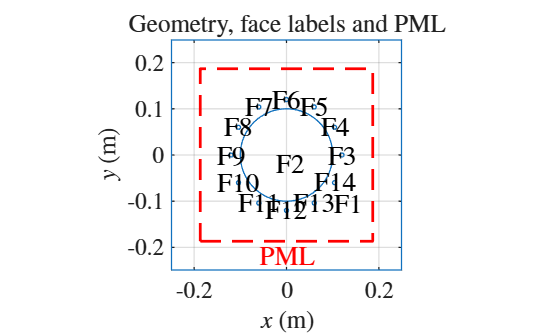

plotGeometry(scenario);

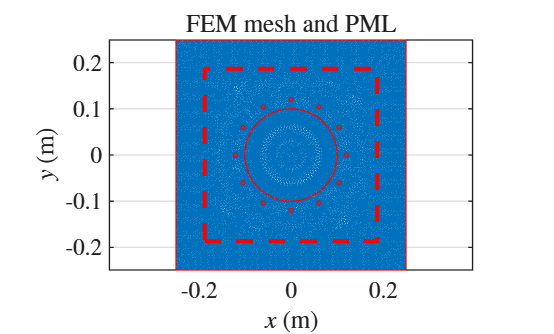

plotMesh(scenario);

## Permittivity

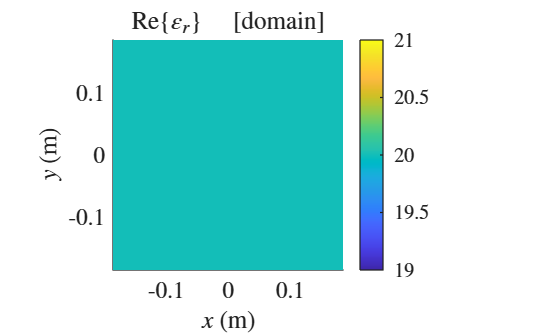

plotPermittivity(domain, 'real');

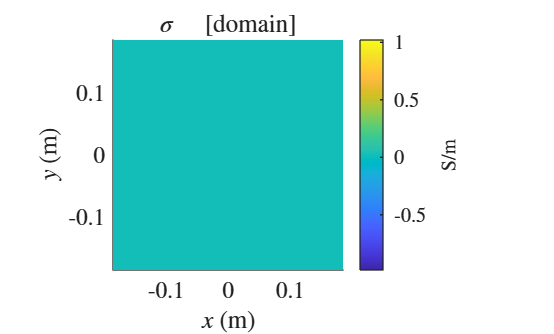

plotPermittivity(domain, 'sigma');

## Field of one transmitter

Choose the transmitter `tx` (the active antenna is marked in red). Tip: in the Live Editor you can turn the number into a slider or spinner (select it, then *Insert > Control*).

Available quantities: `'abs'`, `'dB'`, `'phase'`, `'real'`, `'imag'`.

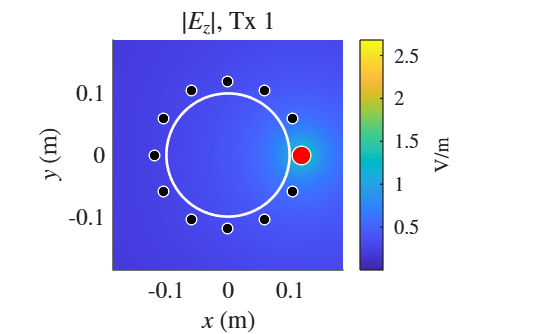

tx = 1;

plotField(domain, tx, 'abs', 'Title', "$|E_z|$, Tx " + tx);

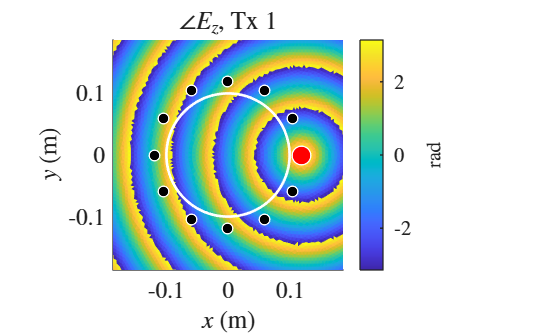

plotField(domain, tx, 'phase', 'Title', "$\angle E_z$, Tx " + tx);

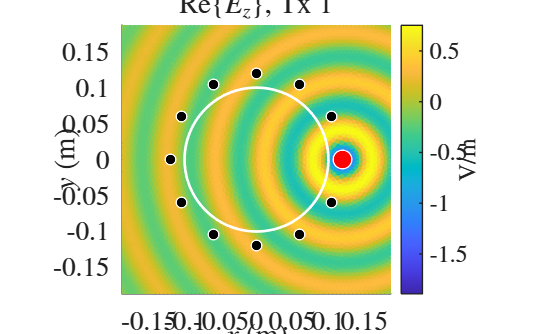

plotField(domain, tx, 'real', 'Title', "$\mathrm{Re}\{E_z\}$, Tx " + tx);

## Field in dB


$$|E|_{dB} = 20\log_{10}\frac{|E|}{\max|E|}$$


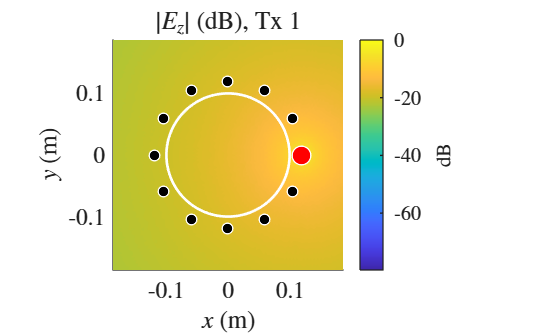

plotField(domain, tx, 'dB', 'Title', "$|E_z|$ (dB), Tx " + tx);

## Interactive viewer

Browse all transmitters and quantities. Colour limits are automatic; untick *Auto* in the window to type your own *Min* / *Max*.

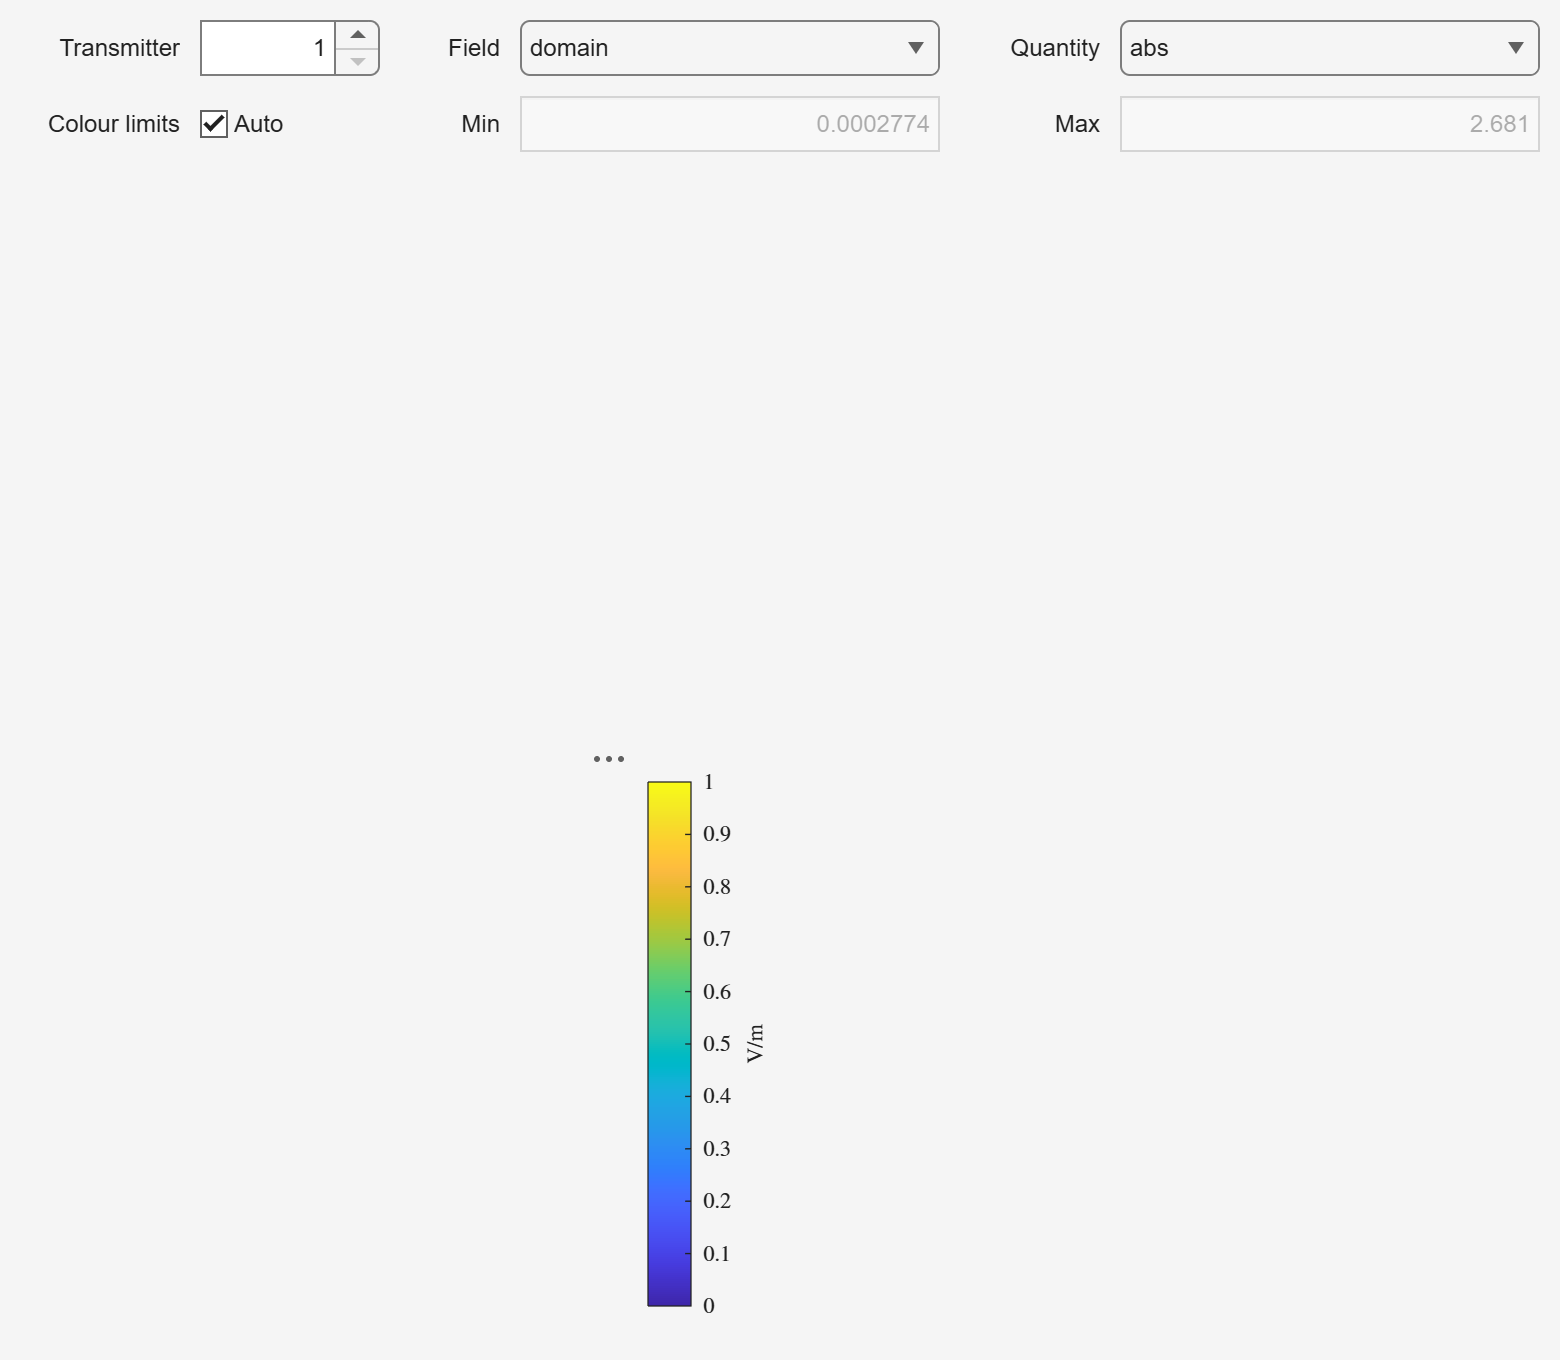

fieldViewer(domain, []);